# Ottimizzazione del turbofan:

Dati i parametri di volo (Mach di volo, altitudine), qualità dei componenti,

ottimizziamo OPR, BPR, TIT e FPR nel cosiddetto "assetto 1", 

ottimizziamo solamente BPR e FPR, con OPR e TIT dati, nel cosiddetto "assetto 2" ,

ottimizziamo OPR e TIT con BPR e FPR dati nell' "assetto 3"

clear variables
close all
clc
assetto = 2; %Scelta delle variabili di ottimizzazione -->ATTENZIONE: Ricordarsi di cambiare
% la funzione di constraint non lineare, purtroppo è una cosa che va fatta a mano ogni volta che si cambiano le variabili di ottimizzazione
obj = "TSFC"; %Scelta dell'obiettivo dell'ottimizzazione

# Inserimento condizioni:


%%qualità componenti
q.e02 = 0.98;
q.pi12 = 1;
q.efan = 0.89;
q.e23 = 0.89;
q.eq = 0.95;
q.piCC = 0.93;
q.e445 = 0.92; %efficienza della turbina di alta pressione
q.e455 = 0.92; %efficienza della turbina di bassa pressione

% parametri ugelli: è possibile scegliere se la loro forma è convergente
% o convergente divergente, e nel secondo caso specificare il rapporto tra
% le aree
u.nozzle = "conv";
u.epsi = 30;
u.nozzle1 = "conv";
u.epsi1 = 30;

% condizioni di volo, fc sta per flight conditions
fc.M0 = 0;
fc.h = 0;
[fc.P0, fc.T0, fc.rho0] = ISA(fc.h);
fc.g = 1.4;
fc.ge = 1.33; %gamma  dei prodotti di combustione
fc.R = 287;
fc.Re = 277.13; %R/massa molare dei prodotti di combustione
fc.m = 44;
fc.L = 42000000;

%   La temperatura è sempre in rapporto a 273.15 gradi Kelvin, in quanto in
%   questo modo le variabili durante l'ottimizzazione sono quasi tutte nello
%   stesso ordine di grandezza ed è possibile notare dove ci sono i
%   maggiori cambiamenti quando si plotta il "best individual"

% Utile nell'assetto 1 e nell'anticipazione grafica: Possiamo far finta di
% conoscere TIT e OPR, così da ottimizzare solo FPR e BPR

if assetto == 1
    %     Assetto 1

    nvars = 4;
    %OPR, BPR, TIT, FPR
    lb = [2, 0, 1000/273.15, 1];
    ub = [30, 10, 1800/273.15, 10];
    x0 = [29, 2, 1400/273.15, 5];
elseif assetto == 2
    %     Assetto 2

    nvars = 2;
    fc.TIT = 1800;
    fc.TIT = fc.TIT/273.15;
    fc.OPR = 45;
    lb = [0, 1];
    ub = [10, 10];
    x0 = [1,1.5];
elseif assetto == 3

    %Assetto 3

    nvars = 2;
    fc.BPR = 0;
    fc.FPR = 0;
    lb = [1, 1000/273.15];
    ub = [30, 1800/273.15];
    x0 = [20, 1400/273.15];
end

# Anticipazione grafica:

Scegliere due variabili per ottenere impulso specifico e consumo specifico.

1) In funzione di BPR e FPR:

if assetto == 2
    x = linspace(lb(1), ub(1), 11);
    y = linspace(lb(2), ub(2));
    [X,Y] = meshgrid(x,y);
    for a = 1:length(x)
        % x(a) è il BPR
        for b = 1:length(y)
            % y(b) è il FPR
            [temp1, temp2, valid] = prestazioni_grafiche([x(a), y(b)],q,u,fc, assetto);
            if valid
                s(b,a) = temp1;   %Lungo le righe cambia il FPR, lungo le colonne cambia il BPR
                tsfc(b,a) = temp2;
            else
                s(b,a) = nan;
                tsfc(b,a) = nan;
            end
        end
    end

    figure(21)
    mesh(X,Y,tsfc)
    title('TSFC con BPR e FPR')
    xlabel('Bypass Ratio')
    ylabel('Fan Pressure Ratio')
    zlabel('Thrust Specific Fuel consumption')
    colorbar
    
    figure(22)
    mesh(X,Y,s)
    title('Spinta con BPR e FPR')
    xlabel('Bypass Ratio')
    ylabel('Fan Pressure Ratio')
    zlabel('Specific Thrust')
    colorbar
  
% Fare un grafico 2D con più linee può risultare più chiaro    
    for a = 1:length(x)
        % x(a) è il BPR
        % y(b) è il FPR
        figure(23)
        plot(y, tsfc(:,a))
        hold on
    end
    leg = "BPR = " + string(x');
    title('TSFC con BPR e FPR')
    xlabel('Fan Pressure Ratio')
    ylabel('TSFC')
    legend(leg, "Location","eastoutside")
    
% Fare un grafico 2D con più linee può risultare più chiaro    
    for a = 1:length(x)
        % x(a) è il BPR
        % y(b) è il FPR
        figure(24)
        plot(y, s(:,a))
        hold on
    end
    leg = "BPR = " + string(x');
    title('S con BPR e FPR')
    xlabel('Fan Pressure Ratio')
    ylabel('S')
    legend(leg, "Location","eastoutside")

2) In funzione di TIT e OPR:

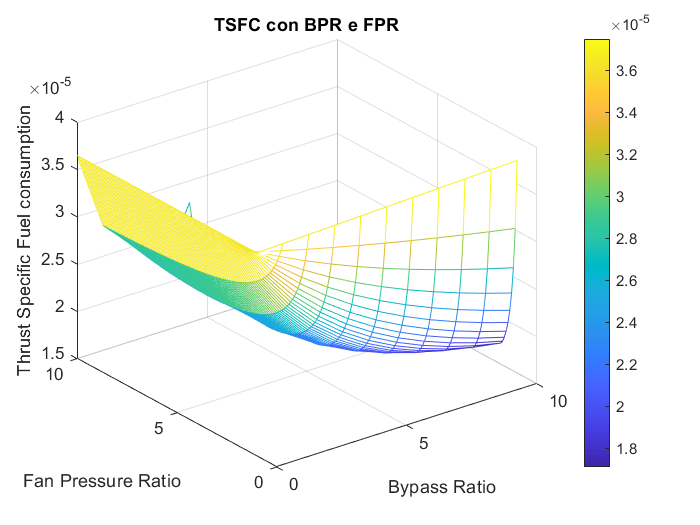

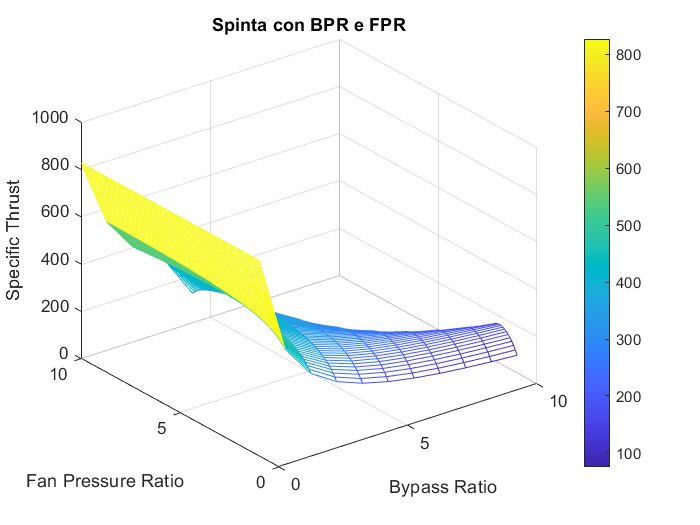

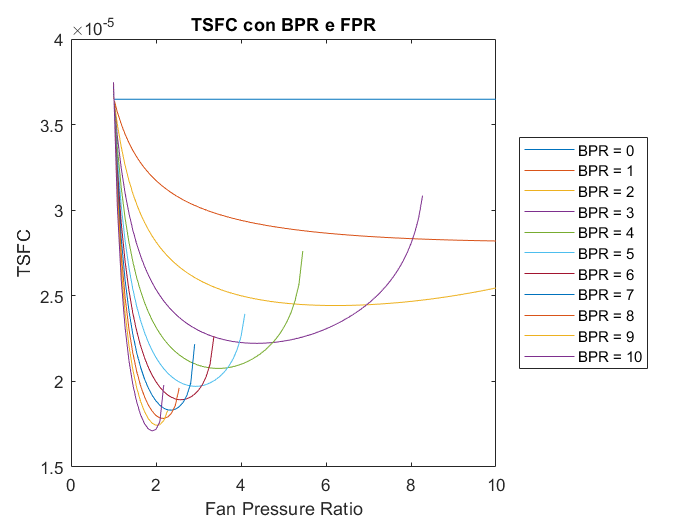

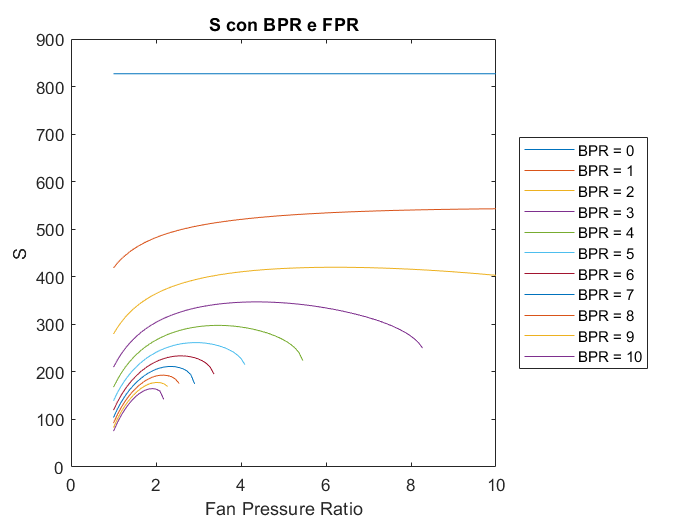

elseif assetto == 3
    x = linspace(lb(1),ub(1));
    y = linspace(lb(2),ub(2));
    for a = 1:length(x)
        % x(a) è l'OPR
        for b = 1:length(y)
            % y(b) è la TIT
            [temp1, temp2, valid] = prestazioni_grafiche([x(a), y(b)],q,u,fc, assetto);
            if valid
                s(b,a) = temp1;   %Lungo le righe cambia la TIT, lungo le colonne cambia l'OPR
                tsfc(b,a) = temp2;
            else
                s(b,a) = nan;
                tsfc(b,a) = nan;
            end
        end
    end
    y = 273.15*y;
    [X,Y] = meshgrid(x,y);

    figure(31)
    contourf(X,Y,tsfc)
    title('TSFC con OPR e TIT')
    xlabel('Overall Pressure Ratio')
    ylabel('Turbine Inlet Temperature')
    zlabel('Thrust Specific Fuel Consumption')
    colorbar
    figure(32)
    mesh(X,Y,s)
    title('Spinta con OPR e TIT')
    xlabel('Overall Pressure Ratio')
    ylabel('Turbine Inlet Temperature')
    zlabel('Specific Thrust')
    colorbar
end

# Ottimizzazione con ga

objfun = @(vars)prestazioni(vars,q,u,fc,assetto,obj);
nonlcon = @(vars)nonlcon4(vars, fc, q, assetto);

options = optimoptions("ga", "PlotFcn","gaplotbestindiv");
[solution, objval, exitflag, output] = ga(objfun, nvars,[],[],[],[],lb,ub,nonlcon,options)

# Ottimizzazione con surrogateopt

% % Pass fixed parameters to objfun
% objfun = @(vars)prestazioni(vars,q,u,fc,assetto,obj);
% nonlcon = @(vars)nonlcon4(vars, fc, q);
% objconstr = packfcn(objfun, nonlcon);
% 
% % Set nondefault solver options
% options = optimoptions('surrogateopt','MaxFunctionEvaluations',500, "Display","final","PlotFcn","optimplotx");
% 
% % Solve
% [solution,objectiveValue, exitflag, output] = surrogateopt(objconstr,lb,ub,[],[],[],[],[],options);

# Ottimizzazione analitica

T4t = fc.TIT*273.15;
Cp = fc.R*fc.g/(fc.g-1);
Cpe = fc.Re*fc.ge/(fc.ge-1);
V0 = fc.M0*sqrt(fc.g*fc.R*fc.T0);
T0t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
P0t = fc.P0*(1+ (fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
%diffusore
if q.e02 ~= 1             %if q.e02 is not given, for M<1 the pressures are equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
    P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
elseif fc.M0>1 && fc.M0<5         %% only if supersonic
    P1t = P0t*(1-0.076*(fc.M0-1)^1.35);
    P2t = P1t*q.pi12;
else
    P1t = P0t;
    P2t = P1t*q.pi12;
end
T2t = T0t;      %supponiamo l'ingresso adiabatico
q.pi12 = P2t/P0t;
q.ed = 1 - (2/((fc.g-1)*fc.M0^2))*(q.pi12^((1-fc.g)/fc.g) -1);
if isnan(q.ed)
    q.ed = 1;
end
Cp = fc.R*fc.g/(fc.g-1);
Cpe = fc.Re*fc.ge/(fc.ge-1);
T2t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
FPRopt = (1 + (1 - q.ed + sqrt(1 - q.ed))*(V0^2)/(Cp*T2t*q.efan))^(fc.g/(fc.g -1));
P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
P3t = P2t*fc.OPR;
T3t = T2t*(1 + (fc.OPR^((fc.g-1)/fc.g) - 1)/q.e23);
Wc = fc.m*Cp*(T3t-T2t);
T4t = fc.TIT*273.15;
f = (Cpe*T4t - Cp*T3t)/(q.eq*fc.L - Cpe*T4t + Cp*T3t);
c = f*fc.m;
me = fc.m + c;
P4t = P3t*q.piCC;
T45t = T4t-Wc/(me*Cpe);
P45t = P4t*(1- (1-T45t/T4t)/q.e445)^(fc.ge/(fc.ge-1));
Vtb = sqrt(2*Cp*(T45t - fc.T0*T4t/T3t));
BPRopt = (1/(2*(1-q.ed+sqrt(1-q.ed))))*((Vtb/(fc.M0*sqrt(fc.g*fc.R*fc.T0)))^2 -(1+sqrt(1-q.ed))^2);

BPRopt2 = 10;
FPRopt2 = (1 + ((q.efan^2)*(q.e445^2)*Vtb^2 - q.ed*V0^2)/(2*q.efan*(1+q.efan*q.e445*BPRopt2)*Cp*T2t))^(fc.g/(fc.g-1));

# Risultati dell'ottimizzazione

switch assetto
    case 1
        
        [S, TSFC, valid] = prestazioni_grafiche(solution, q, u, fc, assetto);
        solution(3) = 273.15*solution(3);
    case 2
        [S, TSFC, valid] = prestazioni_grafiche(solution, q, u, fc, assetto);
        [Sge, TSFCge, validge] = prestazioni_grafiche([9.3, 1.5], q, u, fc, assetto);
        figure(21)
        hold on
        plot3(solution(1),solution(2), TSFC, 'ro')
        drawnow
        figure(22)
        hold on
        plot3(solution(1),solution(2), S, 'ro')
        drawnow
        % Fare un grafico 2D con più linee può risultare più chiaro
        figure(23)
        hold on
        plot(solution(2), TSFC, 'ro', 'DisplayName','opt')
        plot(1.5, TSFCge, 'go', 'DisplayName', 'Ge')
        xlim([1,6])
        ylim([0, 1.5*10^(-5)])
        drawnow
        figure(24)
        hold on
        plot(solution(2), S, 'ro', 'DisplayName','opt')
        plot(1.5, Sge, 'go', 'DisplayName', 'Ge')
        xlim([1,6])
        ylim([200, 500])
        drawnow
        
    case 3
        [S, TSFC, valid] = prestazioni_grafiche(solution, q, u, fc, assetto);
        solution(2) = 273.15*solution(2);
        figure(31)
        hold on
        plot3(solution(1),solution(2), TSFC, 'ro')
        drawnow
        figure(32)
        hold on
        plot3(solution(1),solution(2), S, 'ro')
        drawnow
end

Unrecognized function or variable 'solution'.

function F = prestazioni(vars, q, u, fc, assetto, obj)

if assetto == 1

    %Assetto 1

    OPR = vars(1);
    BPR = vars(2);
    TIT = vars(3);
    FPR = vars(4);
elseif assetto == 2

    %Assetto 2
    OPR = fc.OPR;
    TIT = fc.TIT;
    BPR = vars(1);
    FPR = vars(2);
elseif assetto == 3

    %Assetto 3
    OPR = vars(1);
    TIT = vars(2);
    BPR = fc.BPR;
    FPR = fc.FPR;
end

if BPR == 0  %qui una piccola sovrascrizione, inevitabile, in quanto FPR è ovviamente 0 quando BPR è 0, ma FPR impone il lavoro svolto dalla turbina di bassa pressione
    FPR = 0;
end

T4t = TIT*273.15;

Cp = fc.R*fc.g/(fc.g-1);
Cpe = fc.Re*fc.ge/(fc.ge-1);
V0 = fc.M0*sqrt(fc.g*fc.R*fc.T0);
T0t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
P0t = fc.P0*(1+ (fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
%diffusore
if q.e02 ~= 1             %if q.e02 is not given, for M<1 the pressures are equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
    P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
elseif fc.M0>1 && fc.M0<5         %% only if supersonic
    P1t = P0t*(1-0.076*(fc.M0-1)^1.35);
    P2t = P1t*q.pi12;
else
    P1t = P0t;
    P2t = P1t*q.pi12;
end
T2t = T0t;      %supponiamo l'ingresso adiabatico

%fan
P13t = P2t*FPR;
T13t = T2t*(1+(FPR^((fc.g-1)/fc.g) - 1)/q.efan);
Wf = fc.m*BPR*Cp*(T13t-T2t);

%compressore
P3t = P2t*OPR;
T3t = T2t*(1 + (OPR^((fc.g-1)/fc.g) - 1)/q.e23);
Wc = fc.m*Cp*(T3t-T2t);

%camera di combustione, supponendo che la temperatura di iniezione del
%combustibile sia la stessa di T3t, la quale è approssimata a T3 in
%quanto il Mach in questa sezione è prossimo a zero e quindi possiamo
%approssimare senza perdite eccessive di precisione

f = (Cpe*T4t - Cp*T3t)/(q.eq*fc.L - Cpe*T4t + Cp*T3t);
c = f*fc.m;
me = fc.m + c;
P4t = P3t*q.piCC;

%turbina
T45t = T4t-Wc/(me*Cpe);
P45t = P4t*(1- (1-T45t/T4t)/q.e445)^(fc.ge/(fc.ge-1));
T5t = T45t - Wf/(me*Cpe);
P5t = P45t*(1- (1-T5t/T45t)/q.e455)^(fc.ge/(fc.ge-1));

%controllo se la pressione P5t è maggiore della pressione ambiente
%nella function nonlcon


%ugello primario
if u.nozzle == "conv"
    adapted = false;
    if P5t/fc.P0 <= ((fc.ge+1)/2)^(fc.ge/(fc.ge-1))
        adapted = true;
        Ps = fc.P0;
    end
    if adapted
        Ts = T5t*(fc.P0/P5t)^((fc.ge-1)/fc.ge);
        Ms = sqrt((2/(fc.ge-1))*((P5t/fc.P0)^((fc.ge-1)/fc.ge)-1));
        Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
    else
        Ps = P5t/((fc.ge+1)/2)^(fc.ge/(fc.ge-1));
        Ts = T5t*2/(fc.ge+1);
        Ms = 1;
        Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
    end
    As = me/(Vs*Ps/(fc.Re*Ts));
elseif u.nozzle == "condiv"
    adapted = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
    %per ugello non adattato è necessaria la risoluzione di una equazione non lineare
    G = sqrt(fc.ge)*(2/(fc.ge+1))^((fc.ge+1)/(2*(fc.ge-1)));
    maxeval = 50;
    NPR = 0;
    for i=1:maxeval
        oldNPR = NPR;
        NPR = (G/(u.epsi*sqrt((2*fc.ge/(fc.ge-1))*(1-NPR^((fc.ge-1)/fc.ge)))))^fc.ge;
        if norm((NPR-oldNPR))*100/NPR < 0.1
            i = maxeval;
        end
    end
    Ps = NPR*P5t;
    Ts = T5t*NPR^((fc.ge-1)/fc.ge);
    Ms = sqrt((2/(fc.ge-1))*(T5t/Ts -1));
    Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
    As = me/(Vs*Ps/(fc.Re*Ts));
end
%ugello secondario
if BPR ~= 0
    if u.nozzle1 == "conv"
        adapted1 = false;
        if P13t/fc.P0 <= ((fc.g+1)/2)^(fc.g/(fc.g-1))
            adapted1 = true;
            P1s = fc.P0;
        end
        if adapted1
            T1s = T13t*(fc.P0/P13t)^((fc.g-1)/fc.g);
            M1s = sqrt((2/(fc.g-1))*((P13t/fc.P0)^((fc.g-1)/fc.g)-1));
            V1s = M1s*sqrt(fc.g*fc.R*T1s);
        else
            P1s = P13t/((fc.g+1)/2)^(fc.g/(fc.g-1));
            T1s = T13t*2/(fc.g+1);
            M1s = 1;
            V1s = M1s*sqrt(fc.g*fc.R*T1s);
        end
        A1s = fc.m*BPR/(V1s*P1s/(fc.R*T1s));
    elseif u.nozzle1 == "condiv"
        adapted1 = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
        %%per ugello non adattato è necessaria la risoluzione di una
        %%q.equazione non lineare
        G = sqrt(fc.g)*(2/(fc.g+1))^((fc.g+1)/(2*(fc.g-1)));
        maxeval = 50;
        NPR1 = 0;
        for i=1:maxeval
            oldNPR1 = NPR1;
            NPR1 = (G/(u.epsi1*sqrt((2*fc.g/(fc.g-1))*(1-NPR1^((fc.g-1)/fc.g)))))^fc.g;
            if (NPR1-oldNPR1)*100/NPR1 < 0.1
                i = maxeval;
            end
        end
        P1s = NPR1*P13t;
        T1s = T13t*NPR1^((fc.g-1)/fc.g);
        M1s = sqrt((2/(fc.g-1))*(T13t/T1s -1));
        V1s = M1s*sqrt(fc.g*fc.R*T1s);
        A1s = m1/(V1s*P1s/(fc.R*T1s));
    end
else
    A1s = 0;
    P1s = 0;
    V1s = 0;
end

%Potrebbe succedere che l'espansione sia tale da avere Temperature di
%uscita negative, quindi effettuiamo un check rispetto alla Temperatura
%minima raggiungibile, che è quella del Turbojet corrispondente partendo
%dalla stazione "45": il check è effettuato nella function nonlcon

%prestazioni
E = me*Vs- fc.m*V0 + As*(Ps-fc.P0) + fc.m*BPR*(V1s-V0) + A1s*(P1s-fc.P0);
S = E/(me + fc.m*BPR);
TSFC = c/E;

switch obj
    case 'TSFC'
        F = TSFC;
        %             if (assetto == 2) && (imag(F)==0)
        %                 figure(21)
        %                 hold on
        %                 plot3(BPR, FPR, F, 'ro')
        %                 drawnow
        %             elseif (assetto == 3) && (imag(F)==0)
        %                 figure(31)
        %                 hold on
        %                 plot3(OPR, TIT*273.15, F, 'ro')
        %                 drawnow
        %             end
    case 'S'
        F = -S;
        %             if (assetto == 2) && (imag(S)==0)
        %                 figure(22)
        %                 hold on
        %                 plot3(BPR, FPR, S, 'ro')
        %                 drawnow
        %             elseif (assetto == 3) && (imag(S)==0)
        %                 figure(32)
        %                 hold on
        %                 plot3(OPR, TIT*273.15, S, 'ro')
        %                 drawnow
        %             end
    case 'surrogateTSFC'
%         esp = (fc.g-1)/fc.g;
%         espe = (fc.ge)/(fc.ge -1);
%         F.Ineq = [fc.P0-P2t*OPR*((1 - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e445*T4t*q.e23))^espe)*(1 - Cp*T2t*BPR*(FPR^esp - 1)/((1+f)*Cpe*q.e455*q.efan*(T4t - Cp*T2t*(OPR^esp - 1)/((1+f)*Cpe*q.e23))))^espe; (fc.P0^((fc.ge-1)/fc.ge))*(T4t - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e23))/(((OPR*P2t)^((fc.ge-1)/fc.ge))*(1 - (Cp*T2t)*(OPR^esp -1)/((1+f)*q.e445*T4t*Cpe*q.e23)))-Ts];
        F = TSFC;
        %             if (assetto == 2) && (imag(F.Fval)==0)
        %                 figure(21)
        %                 hold on
        %                 plot3(BPR, FPR, F.Fval, 'ro')
        %                 drawnow
        %             elseif (assetto == 3) && (imag(F.Fval)==0)
        %                 figure(31)
        %                 hold on
        %                 plot3(OPR, TIT*273.15, F.Fval, 'ro')
        %                 drawnow
        %             end
    case 'surrogateS'
%         esp = (fc.g-1)/fc.g;
%         Ttj = (fc.P0^((fc.ge-1)/fc.ge))*(T4t - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e23))/(((OPR*P2t)^((fc.ge-1)/fc.ge))*(1 - (Cp*T2t)*(OPR^esp -1)/((1+f)*q.e445*T4t*Cpe*q.e23)));
%         F.Ineq = [fc.P0-P5t; Ttj-Ts];
        F = -S;
        %             if (assetto == 2) && (imag(S)==0)
        %                 figure(22)
        %                 hold on
        %                 plot3(BPR, FPR, S, 'ro')
        %                 drawnow
        %             elseif (assetto == 3) && (imag(S)==0)
        %                 figure(32)
        %                 hold on
        %                 plot3(OPR, TIT*273.15, S, 'ro')
        %                 drawnow
        %             end
    otherwise
        error('Obiettivo sconosciuto')
end
%     Va specificato che l'algoritmo di ottimizzazione 'surrogate' pretende il
%     constraint non lineare all'interno della funzione obiettivo

%     Ricorda che surrogate prima prova dei punti e poi vede se la loro
%     posizione è fattibile dati i constraint, quindi togli il plot in
%     quanto potrebbe andare in errore con dei valori di TSFC complessi
%     (che capitano nel momento in cui non si tiene conto del constraint
%     della temperatura di uscita, dando una velocità di uscita complessa
%     dato che è data dalla radice quadrata di Ts, negativa se non teniamo conto
%     del constraint)

end

# Funzione di prestazioni per anticipazioni grafiche:

function [S, TSFC, valid] = prestazioni_grafiche(vars, q, u, fc, assetto)

%Nelle previsioni grafiche siamo sempre in assetto 2 o 3

if assetto == 1
    
    %Assetto 1

    OPR = vars(1);
    BPR = vars(2);
    TIT = vars(3);
    FPR = vars(4);
elseif assetto == 2

    %Assetto 2
    OPR = fc.OPR;
    TIT = fc.TIT;
    BPR = vars(1);
    FPR = vars(2);
elseif assetto == 3

    %Assetto 3
    OPR = vars(1);
    TIT = vars(2);
    BPR = fc.BPR;
    FPR = fc.FPR;
end

if BPR == 0  %qui una piccola sovrascrizione, inevitabile, in quanto FPR è ovviamente 0 quando BPR è 0, ma FPR impone il lavoro svolto dalla turbina di bassa pressione
    FPR = 0;
end

T4t = TIT*273.15;

Cp = fc.R*fc.g/(fc.g-1);
Cpe = fc.Re*fc.ge/(fc.ge-1);
V0 = fc.M0*sqrt(fc.g*fc.R*fc.T0);
T0t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
P0t = fc.P0*(1+ (fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
%diffusore
if q.e02 ~= 1             %if q.e02 is not given, for M<1 the pressures are q.equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
    P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
elseif fc.M0>1 && fc.M0<5         %% only if supersonic
    P1t = P0t*(1-0.076*(fc.M0-1)^1.35);
    P2t = P1t*q.pi12;
else
    P1t = P0t;
    P2t = P1t*q.pi12;
end
T2t = T0t;      %supponiamo l'ingresso adiabatico

%fan
P13t = P2t*FPR;
T13t = T2t*(1+(FPR^((fc.g-1)/fc.g) - 1)/q.efan);
Wf = fc.m*BPR*Cp*(T13t-T2t);

%compressore
P3t = P2t*OPR;
T3t = T2t*(1 + (OPR^((fc.g-1)/fc.g) - 1)/q.e23);
Wc = fc.m*Cp*(T3t-T2t);

%camera di combustione, supponendo che la temperatura di iniezione del
%combustibile sia la stessa di T3t, la quale è approssimata a T3 in
%quanto il Mach in questa sezione è prossimo a zero e quindi possiamo
%approssimare senza perdite eccessive di precisione

f = (Cpe*T4t - Cp*T3t)/(q.eq*fc.L - Cpe*T4t + Cp*T3t);
c = f*fc.m;
me = fc.m + c;
P4t = P3t*q.piCC;

valid = true;
if f<=0
    valid = false;
end

%turbina
T45t = T4t-Wc/(me*Cpe);
P45t = P4t*(1- (1-T45t/T4t)/q.e445)^(fc.ge/(fc.ge-1));
T5t = T45t - Wf/(me*Cpe);
P5t = P45t*(1- (1-T5t/T45t)/q.e455)^(fc.ge/(fc.ge-1));

%controllo se la pressione P5t è maggiore della pressione ambiente

esp = (fc.g-1)/fc.g;
espe = (fc.ge)/(fc.ge -1);
% if fc.P0 - P2t*OPR*((1 - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e445*T4t*q.e23))^espe)*(1 - Cp*T2t*BPR*(FPR^esp - 1)/((1+f)*Cpe*q.e455*q.efan*(T4t - Cp*T2t*(OPR^esp - 1)/((1+f)*Cpe*q.e23))))^espe > 0
%     valid = false;
% end
if fc.P0 > P5t
    valid = false;
end

%ugello primario
if u.nozzle == "conv"
    adapted = false;
    if P5t/fc.P0 <= ((fc.ge+1)/2)^(fc.ge/(fc.ge-1))
        adapted = true;
        Ps = fc.P0;
    end
    if adapted
        Ts = T5t*(fc.P0/P5t)^((fc.ge-1)/fc.ge);
        Ms = sqrt((2/(fc.ge-1))*((P5t/fc.P0)^((fc.ge-1)/fc.ge)-1));
        Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
    else
        Ps = P5t/((fc.ge+1)/2)^(fc.ge/(fc.ge-1));
        Ts = T5t*2/(fc.ge+1);
        Ms = 1;
        Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
    end
    As = me/(Vs*Ps/(fc.Re*Ts));
elseif u.nozzle == "condiv"
    adapted = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
    %%per ugello non adattato è necessaria la risoluzione di una
    %%equazione non lineare
    G = sqrt(fc.ge)*(2/(fc.ge+1))^((fc.ge+1)/(2*(fc.ge-1)));
    maxeval = 50;
    NPR = 0;
    for i=1:maxeval
        oldNPR = NPR;
        NPR = (G/(u.epsi*sqrt((2*fc.ge/(fc.ge-1))*(1-NPR^((fc.ge-1)/fc.ge)))))^fc.ge;
        if norm((NPR-oldNPR))*100/NPR < 0.1
            i = maxeval;
        end
    end
    Ps = NPR*P5t;
    Ts = T5t*NPR^((fc.ge-1)/fc.ge);
    Ms = sqrt((2/(fc.ge-1))*(T5t/Ts -1));
    Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
    As = me/(Vs*Ps/(fc.Re*Ts));
end
%ugello secondario
if BPR ~= 0
    if u.nozzle1 == "conv"
        adapted1 = false;
        if P13t/fc.P0 <= ((fc.g+1)/2)^(fc.g/(fc.g-1))
            adapted1 = true;
            P1s = fc.P0;
        end
        if adapted1
            T1s = T13t*(fc.P0/P13t)^((fc.g-1)/fc.g);
            M1s = sqrt((2/(fc.g-1))*((P13t/fc.P0)^((fc.g-1)/fc.g)-1));
            V1s = M1s*sqrt(fc.g*fc.R*T1s);
        else
            P1s = P13t/((fc.g+1)/2)^(fc.g/(fc.g-1));
            T1s = T13t*2/(fc.g+1);
            M1s = 1;
            V1s = M1s*sqrt(fc.g*fc.R*T1s);
        end
        A1s = fc.m*BPR/(V1s*P1s/(fc.R*T1s));
    elseif u.nozzle1 == "condiv"
        adapted1 = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
        %%per ugello non adattato è necessaria la risoluzione di una
        %%equazione non lineare
        G = sqrt(fc.g)*(2/(fc.g+1))^((fc.g+1)/(2*(fc.g-1)));
        maxeval = 50;
        NPR1 = 0;
        for i=1:maxeval
            oldNPR1 = NPR1;
            NPR1 = (G/(u.epsi1*sqrt((2*fc.g/(fc.g-1))*(1-NPR1^((fc.g-1)/fc.g)))))^fc.g;
            if (NPR1-oldNPR1)*100/NPR1 < 0.1
                i = maxeval;
            end
        end
        P1s = NPR1*P13t;
        T1s = T13t*NPR1^((fc.g-1)/fc.g);
        M1s = sqrt((2/(fc.g-1))*(T13t/T1s -1));
        V1s = M1s*sqrt(fc.g*fc.R*T1s);
        A1s = m1/(V1s*P1s/(fc.R*T1s));
    end
else
    A1s = 0;
    P1s = 0;
    V1s = 0;
end

%Potrebbe succedere che l'espansione sia tale da avere Temperature di
%uscita negative, quindi effettuiamo un check rispetto alla Temperatura
%minima raggiungibile, che è quella del Turbojet corrispondente partendo
%dalla stazione "45"

% if Ts < (fc.P0^((fc.ge-1)/fc.ge))*(T4t - Cp*T2t*(OPR^(esp) -1)/((1+f)*Cpe*q.e23))/(((OPR*P2t)^((fc.ge-1)/fc.ge))*(1 - (Cp*T2t)*(OPR^(esp) -1)/((1+f)*q.e445*T4t*Cpe*q.e23)))
%     valid = false;
% end
if Ts < 0
    valid = false;
end
%prestazioni
E = me*Vs- fc.m*V0 + As*(Ps-fc.P0) + fc.m*BPR*(V1s-V0) + A1s*(P1s-fc.P0);
S = E/(me + fc.m*BPR);
if S <0
    valid = false;
end
TSFC = c/E;

end

# Constraint non lineare

function [cineq, ceq] = nonlcon4(vars, fc, q, assetto)


if assetto == 1

    %Assetto 1

    OPR = vars(1);
    BPR = vars(2);
    TIT = vars(3);
    FPR = vars(4);
elseif assetto == 2

    %Assetto 2
    OPR = fc.OPR;
    TIT = fc.TIT;
    BPR = vars(1);
    FPR = vars(2);
elseif assetto == 3

    %Assetto 3
    OPR = vars(1);
    TIT = vars(2);
    BPR = fc.BPR;
    FPR = fc.FPR;
end

if BPR == 0
    FPR = 0;
end

T4t = TIT*273.15;
P0t = fc.P0*(1+ (fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
if q.e02 ~= 1             %if q.e02 is not given, for M<1 the pressures are q.equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
    P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
elseif fc.M0>1 && fc.M0<5         %% only if supersonic
    P1t = P0t*(1-0.076*(fc.M0-1)^1.35);
    P2t = P1t*q.pi12;
else
    P1t = P0t;
    P2t = P1t*q.pi12;
end
T2t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
Cp = fc.R*fc.g/(fc.g-1);
Cpe = fc.Re*fc.ge/(fc.ge-1);

f = (Cpe*T4t - Cp*T2t*(1 + (OPR^((fc.g-1)/fc.g) - 1)/q.e23))/(q.eq*fc.L - Cpe*TIT + Cp*T2t*(1 + (OPR^((fc.g-1)/fc.g) - 1)/q.e23));

esp = (fc.g-1)/fc.g;
espe = (fc.ge)/(fc.ge -1);

P5t = P2t*OPR*((1 - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e445*T4t*q.e23))^espe)*(1 - Cp*T2t*BPR*(FPR^esp - 1)/((1+f)*Cpe*q.e455*q.efan*(T4t - Cp*T2t*(OPR^esp - 1)/((1+f)*Cpe*q.e23))))^espe;
T5t = T4t - T2t*Cp*(OPR^esp -1)/((1+f)*Cpe*q.e23) - T2t*BPR*Cp*(FPR^esp -1)/((1+f)*Cpe*q.efan);

%Potrebbe succedere che l'espansione sia tale da avere Temperature di
%uscita negative, quindi effettuiamo un check rispetto alla Temperatura
%minima raggiungibile, che è quella del Turbojet dalla stazione "45"

adapted = false;
if P5t/fc.P0 <= ((fc.ge+1)/2)^espe
    adapted = true;
    Ps = fc.P0;
end
if adapted
    Ts = T5t*(fc.P0/P5t)^((fc.ge-1)/fc.ge);
else
    Ts = T5t*2/(fc.ge+1);
end

%     Ttj = (fc.P0^((fc.ge-1)/fc.ge))*(T4t - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e23))/(((OPR*P2t)^((fc.ge-1)/fc.ge))*(1 - (Cp*T2t)*(OPR^esp -1)/((1+f)*q.e445*T4t*Cpe*q.e23)));

%controllo se la pressione P5t è maggiore della pressione ambiente

cineq = [fc.P0 - P5t; -Ts];
ceq = [];
end